 clear all
import ebfret.analysis.*

%%change directory to where your trace files are at
cd = 'Z:\Darcy\DNA Origami\2019 smHinge\dsDNA 3.3.3 9bp\AllConcForAnalysis'

cd = 'Z:\Darcy\DNA Origami\2019 smHinge\dsDNA 3.3.3 9bp\AllConcForAnalysis'


%% change this to match your acquisition rate
secperFrame = 1;

%%get all filenames that you want to analyze
files = dir('*agreggatecatcut.mat')

files = 8×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filecounter = 1;

%%panel is a package that allows dynamic resizing of multiple plots side by
%%side
pan = panel();

%%these arrays are for storing the parameter outputs of the fitting
%%procedure: the amplitude of the decay A and the corresponding rates k1
%%and k2 for both transitions from high states and transitions from low
%%states

Ahigh = [];
Alow = [];
k1high = [];
k1low = [];
k2high = [];
k2low = [];

%%I thought it looked best with figures packed into a 3x5 grid
pan.pack(3, 5);

save_name = '10nMagreggatecatcut.matsave.dat'

mat_save_name = 'plotsave10nMagreggatecatcut.mat'

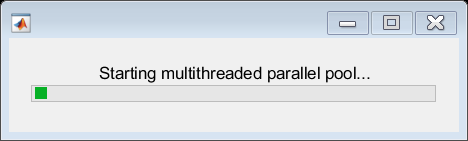

Error using parpool (line 113)
Found an interactive session. You cannot have multiple interactive sessions open simultaneously. To terminate the existing session, use 'delete(gcp('nocreate'))'.

Error in eb_fret_waitbar (line 83)
        parpool(opts.num_cpu);

%%now we want to analyze each file separately
for file = files'
    
    %file.namedat = strcat(char(file.name),'.dat')
    %formatEB(char(file.name) ,file.namedat);%% ebFRET part
    
    
    %%these are for saving the data (aka fit traces) and plots (aka parameters and dwell
    %%times) 
    save_name = strcat(file.name, 'save.dat')
    mat_save_name = strcat('plotsave', file.name)
     
    %%These parameters are for ebFRET. K_values is how many states to use
    %%for each run and can be a list [2 3 4] if desired
    K_values = [2];
    %%restarts is how many times should we attempt the entire fitting and
    %%then take the best attempt
    restarts = 3;
    %%this is how many cores we have in the parallel computing pool
    num_cpu = 4;
    
    
    
    % options for loading and stripping traces, see load_fret_defaults and
    % eb_defaults for more info
    
    
    %% write more comments here
    opts.load_fret = load_fret_defaults();
    
    opts.load_fret.min_length = 50;
    
    opts.load_fret.max_outliers = 1;
    
    opts.load_fret.strip_first = true;
    
    opts.load_fret.remove_bleaching = true;
    
    
    
    % options for vbem algorithm
    
    opts.eb = eb_defaults();
    [data, raw] = load_fret(file.name, 'variable', 'data');
    
    
    %% here we actually do the eb_fret fitting.
    runs = eb_fret_waitbar(data.fret, K_values, restarts...
        , 'eb', opts.eb, 'num_cpu', num_cpu);
    

   % w = runs.vb.w;
   % u = runs.u;
   % M_values =2 ;
   % test = eb_fret_pmm_dir(data.fret, w , u, 2);    
    
    %%This line ends the parallel pool. If you stop the program while it is
    %%fitting traces, you will need to close the parallel pool with this
    %%command in console or the script wil
    % l crash when it tries to open a
    %%new pool on top of the old one.
    delete(gcp('nocreate'))

   
    %%runs.vit contains the Viterbi idealized traces.
    dummy = struct2table(runs.vit);
    
    %%now we need to put it into the right structure to extract dwell times
    for i = 1:length(dummy.z)
        cellpaths{i,1} = i*ones(length(cell2mat(dummy.x(i))),1);
        cellpaths{i,2} = cell2mat(dummy.x(i));
    end
    
    paths = cell2mat(cellpaths);
    
    %% here we save the fret traces and idealized fits to the filename we made before
    save(save_name, 'paths', '-ascii')
    
    
    pan(filecounter, 1).select();
    
    %plot Transition Density Plot from eb_FRET fitted traces
    
    plot_TDP_panel(save_name)
    
    
   %%% [rep, par] = hmm.report ({runs.vit}, runs.u, runs.u0)
    
    %%%print (rep(:).Parameters.Transition_Matrix.Mean)
    %%%print (rep(:).Parameters.Transition_Matrix.std)
    
    %%run eb_dwelltimes to extract the list of dwell times from the
    %%idealized traces. thigh and tlow are unordered lists of dwell times.
    %%histTlow and histThigh are ordered histograms, and cumtlow and
    %%cumthigh are cumulative ordered histograms.
   [thigh, tlow, histTlow, histThigh, cumtlow, cumthigh] = eb_dwelltimes(cellpaths(:,2), secperFrame);
    
    
    pan(filecounter, 2).select();
    %%% PLOT CUMULATIVE DISTRIBUTION
    
    %%ecdf makes a cumulative distribution function (cdf) out of the high
    %%dwell times
    [F_high, X_high] = ecdf(thigh);
    %%saves the high dwell times cdf
    save(mat_save_name, 'F_high', 'X_high')
    %%plot high dwell times 
    plot (X_high, F_high, 'ko')
    hold on
    
    %%% PLOT DOUBLE EXPONENTIAL FIT
    %% get a probability density function for double exponential
    [userPDF, dataVar, fitVar, lb,ub, guess]=PDFList('Double Exp (Independent)', 'all', 0);
    
    %%these are the upper bound, initial guess, and annealing temperature
    %%of the fitting. These are worth tuning if you are finding your fits
    %%are poor
    ub = '1,100,100';
    guess = '0.5,1,0.1';
    annealTemp=5;  
    
    %% MEMLET is a maximum liklihood fitting program. It fits a double
    %%userPDF to the data using the parameters we set earlier. The 
    %%outputs are the fit results in an array I've called stat high d
    %%for statistics high dwell time double exponential
    [stathighd, oriLLH]= MEMLETCL(thigh', userPDF, dataVar, fitVar, lb,ub, guess,annealTemp)
    
    %%one problem with these programs is that if you ask for statistics
    %%about k1 then it will give you symmetric statistics about both
    %%parameters. The following statement enforces the convention that k1
    %%is the faster rate.
    if (stathighd(2) < stathighd(3))
        stathighd(1) = 1- stathighd(1)
        stathighd([2 3]) = stathighd([3 2])
    end
    plotVarx=linspace(0,max(thigh),10000)'; %create variables for plotting along x
   
    fitteddh=dbexppdfnotmin(plotVarx,stathighd);  
    fittedCDF=cumtrapz(fitteddh(~isnan(fitteddh))); %take out any NaNs when doing cumulative (maybe at x=0?) 
    fittedCDFh=fittedCDF/max(fittedCDF); %normalize CDF
     
    plot(plotVarx(~isnan(fitteddh)),fittedCDFh,'r', 'LineWidth', 2)
    
    hold on
    %%% PLOT SINGLE EXPONENTIAL FIT 
    [userPDF, dataVar, fitVar, lb,ub, guess]=PDFList('Single Exp', 'all', 0);
    annealTemp=5;
    guess = '1';
    
    [stathigh, logLikli]= MEMLETCL(thigh', userPDF, dataVar, fitVar, lb,ub, guess,annealTemp)
    
    
    plotVarx=linspace(0,max(thigh),10000)'; %create variables for plotting along x
    
    fittedsh= exppdfcalcnotmin(plotVarx, stathigh) ;
    fittedCDF1=cumtrapz(fittedsh(~isnan(fittedsh))); %take out any NaNs when doing cumulative (maybe at x=0?) 
    fittedCDF2=fittedCDF1/max(fittedCDF1); %normalize CDF
    
    %plot(plotVarx(~isnan(fittedsh)),fittedCDF2)
    
    title('High Dwell Times  ')
    delDF = 2; %% two constraints on double exp yields single exp, hence 2
    RLL=2*(oriLLH-logLikli); % the log of the ratio of  the likelihoods 

    p=1-chi2cdf(RLL,delDF) %calculate a p-value from the chi2cdf
    if p == 1
        p = '> 1 - 1e-16';
    elseif p == 0
        p = '< 1e-16';
    else
        p = num2str(p);
    end
    txt = {strcat('A: ' , num2str(round(stathighd(1),3))) ...
        strcat('k1: ' , num2str(round(stathighd(2),3))) strcat('k2: ' , num2str(round(stathighd(3),3)))...
        ' ' strcat('k: ', num2str(round(stathigh,3))) strcat('P-value: ', p)};
       
    %text('string', txt , 'units', 'normalized', 'position', [0.5 0.5])
    xlabel('Time (s) for 5Hz')
    %max(thigh),0.5
    
    %%this part plots the fit function and points for the single
    %%exponential
    howmanyeventsgraphed = .95
    [~, closestIndex] = min(abs(howmanyeventsgraphed - F_high.'))
    set(gca, 'YScale', 'log')
    axis([-.05*X_high(closestIndex) X_high(closestIndex) F_high(2)/1.3 1]) 
    
    hold off
    
    
    %%%%%%% LOW DWELL TIMES %%%%%%
    
    pan(filecounter, 3).select();
    %%PLOT CUMULATIVE DISTRIBUTION

    [F_low, X_low] = ecdf(tlow)
    
    plot (X_low,F_low, 'ko')
    hold on
    %%% PLOT DOUBLE EXPONENTIAL FIT
    [userPDF, dataVar, fitVar, lb,ub, guess]=PDFList('Double Exp (Independent)', 'all', 0);
    ub = '1,100,100';
    guess = '0.5,1,0.1';
    annealTemp=5;  
    
    
    [statlowd, oriLLH]= MEMLETCL(tlow', userPDF, dataVar, fitVar, lb,ub, guess,annealTemp)
    plotVarx=linspace(0,max(tlow),10000)'; %create variables for plotting along x
    if (statlowd(2) < statlowd(3))
        statlowd(1) = 1- statlowd(1)
        statlowd([2 3]) = statlowd([3 2])
    end
    
    fitteddl=dbexppdfnotmin(plotVarx,statlowd);  
    fittedCDF=cumtrapz(fitteddl(~isnan(fitteddl))); %take out any NaNs when doing cumulative (maybe at x=0?) 
    fittedCDFl=fittedCDF/max(fittedCDF); %normalize CDF
    
    
    
    plot(plotVarx(~isnan(fitteddl)),fittedCDFl,'r', 'LineWidth', 2)
    hold on
    
    %%%PLOT SINGLE EXPONENTIAL FIT
    [userPDF, dataVar, fitVar, lb,ub, guess]=PDFList('Single Exp', 'all', 0);
    guess = '1';
    annealTemp=5; 
    [statlow, logLikli]= MEMLETCL(tlow', userPDF, dataVar, fitVar, lb,ub, guess,annealTemp)
    
    plotVarx=linspace(0,max(tlow),10000)'; %create variables for plotting along x
    
    fittedsl= exppdfcalcnotmin(plotVarx, statlow) ;
    fittedCDF1=cumtrapz(fittedsl(~isnan(fittedsl))); %take out any NaNs when doing cumulative (maybe at x=0?) 
    fittedCDF2=fittedCDF1/max(fittedCDF1); %normalize CDF
    
    %plot(plotVarx(~isnan(fittedsl)),fittedCDF2)
    title('Low Dwell Times')
    
    delDF = 2; %% two constraints on double exp yields single exp, hence 2
    RLL=2*(oriLLH-logLikli); % the log of the ratio of  the likelihoods 

    p=1-chi2cdf(RLL,delDF) %calculate a p-value from the chi2cdf
    if p == 1
        p = '> 1 - 1e-16';
    elseif p == 0
        p = '< 1e-16';
    else
        p = num2str(p);
    end
    
    txt = {strcat('A: ' , num2str(round(statlowd(1),3))) ...
        strcat('k1: ' , num2str(round(statlowd(2),3))) strcat('k2: ' , num2str(round(statlowd(3),3)))...
        ' ' strcat('k: ', num2str(round(statlow,3))) strcat('P-value: ', p)};
    
    ax = gca;
    
    %text('string', txt , 'units', 'normalized', 'position', [0.5 0.5])
    xlabel('Time (s) for 5Hz')
    %max(thigh),0.5
    howmanyeventsgraphed = .95
    [~, closestIndex] = min(abs(howmanyeventsgraphed - F_low.'))
    set(gca, 'YScale', 'log')
    axis([-.05*X_low(closestIndex) X_low(closestIndex) F_low(2)/1.3 1]) 
    
    
    save (mat_save_name, 'F_low', 'X_low', 'F_high', 'X_high', 'stathighd', 'statlowd', 'fitteddl', 'fittedCDFl', 'fitteddh', 'fittedCDFh', 'thigh', 'tlow', 'statlow','stathigh')
    %%export data needed for plotting
    
    hold off

    pan(filecounter, 4).select();
    bar(find(histThigh)/5, histThigh(find(histThigh))/max(cumthigh)*5, 1)
    hold on
    semilogy(plotVarx(~isnan(fitteddh)), fitteddh,'color', [0.8500 0.3250 0.0980], 'LineWidth', 2)
    set(gca, 'YScale', 'log')
    %semilogy(plotVarx(~isnan(fittedsh)), fittedsh, 'color', [0.9290 0.6940 0.1250])
    
    
    axis([-1  5 .01 1])
    title(strcat('High Dwell Times Semilog Histogram'))
    xlabel('Time (s) for 5Hz')
    ylabel('Normalized Counts')
    hold off
    
    pan(filecounter, 5).select();
    bar(find(histTlow)/5, histTlow(find(histTlow))/max(cumtlow)*5, 1 )
    hold on
    semilogy(plotVarx(~isnan(fitteddl)), fitteddl, 'color', [0.8500 0.3250 0.0980], 'LineWidth', 2)
    set(gca, 'YScale', 'log')
    %semilogy(plotVarx(~isnan(fittedsl)), fittedsl, 'color', [0.9290 0.6940 0.1250])
    
   
    axis([-1 5 .01 1])
    title(strcat('Low Dwell Times Semilog Histogram'))
    xlabel('Time (s) for 5Hz')
    ylabel('Normalized Counts')
    
    
    hold off

    
    if mod(filecounter,3) == 0
        pan = panel();
        pan.pack(3, 5);
        filecounter = 1
    else
        filecounter = filecounter + 1
    end
    if strcmp(p,'< 1e-16')
        Ahigh(end + 1) = stathighd(1)
        Alow(end + 1) = statlowd(1)
        k1high(end + 1) = max([stathighd(2), stathighd(3)])
        k2high(end + 1) = min([stathighd(2), stathighd(3)])
        k1low(end + 1) = max([statlowd(2), statlowd(3)])
        k2low(end + 1) = min([statlowd(2), statlowd(3)])
    else
        display("p-value to reject null hypothesis >1E-16")
    end
    set(gcf, 'Color', [1,1,1]);
    clear data paths cellpaths dummy runs
end
disp( strcat('High dwell amplitude mean:', num2str(mean(Ahigh(1:(end-1)))) ,' std: ' ,num2str(std(Ahigh(1:(end-1))))))
disp( strcat('High dwell k1 mean:', num2str(mean(k1high(1:(end-1)))) ,' std: ' ,num2str(std(k1high(1:(end-1))) ) ))
disp( strcat('High dwell k2 mean:', num2str(mean(k2high(1:(end-1)))) ,' std: ' ,num2str(std(k2high(1:(end-1))) ) ))
disp( strcat('Low Dwell amplitude mean:',num2str(mean(Alow(1:(end-1)))) ,' std: ', num2str(std(Alow(1:(end-1))) )))
disp( strcat('Low dwell k1 mean:',num2str(mean(k1low(1:(end-1)))) ,' std: ' ,num2str(std(k1low(1:(end-1))))))
disp( strcat('Low dwell k1 mean:',num2str(mean(k2low(1:(end-1)))) ,' std: ' ,num2str(std(k2low(1:(end-1))))))